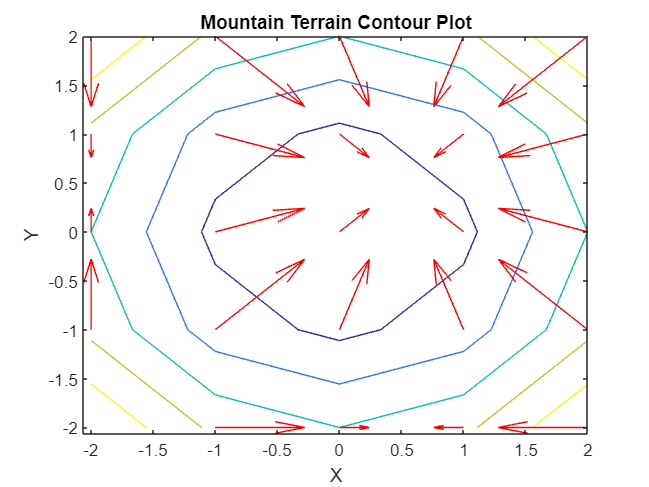

clc
% Define the mountain-like terrain function
[X, Y] = meshgrid(-2:1:2, -2:1:2);
Z = X.^2+ Y.^2;

% Create a grid of x and y values
x = -2:0.5:2;
y = -2:0.5:2;

% Calculate the gradient of the terrain function using finite differences
[dx, dy] = meshgrid(0.5, 0.5);
grad_x = (Z - circshift(Z, [0, 1])) / dx;
grad_y = (Z - circshift(Z, [1, 0])) / dy;

% Create a contour plot to visualize the terrain
figure;
contour(X, Y, Z, 5);
xlabel('X');
ylabel('Y');
title('Mountain Terrain Contour Plot');

% Add quiver plot to show gradient vectors
hold on;
quiver(X, Y, -grad_x, -grad_y, 'r'); % 'r' for red color